# Drainage reorganization

Rivers are mobile and move around in time and space, thereby shaping the landscape around them. Last time we focused on river profiles. Int the first part of this script, we focus on the planform geometry of rivers and how river basins change their shape through time. This may sound like some unimportant theoretical process of nerd ivory tower science. However, rivers are the main agents of landscape evolutiion and typical control most aspects of a landscape. Drainage divides separating rivers are by definition always the highest parts of the landscape. Therefore, moving draining divides around has a large effect on climate (orographic effects at drainage divides govern many of our planets large weather patterns), ecology (e.g., separating populations of species through topographic barriers), and hydrology (drainage divide locations determine where the water flows and sediment and nutirents with it!). 

Here's a recent review article about the migration of drainage divides through time and its implications for life and climate. 

[Drainage divide migration and implications for climate and biodiversity | Nature Reviews Earth & Environment](https://www.nature.com/articles/s43017-023-00511-z)

This being said, southwestern Germany is among the best places in the world to study the movement of drainage divides. The whole region went through a major change in river flow patterns over the course of the past few million years. Here the two largest European river (if we exclude Russia): Rhine and Danube meet and compete in an epic battle for drainage area. Let's try to uncover this history by just using elevation data.

clc
clear 
close all
DEM =  % load DEM
DEM.Z  % condition DEM that streams don't flow south. Make last row of raster = 2000m elevation 
DEM.Z(DEM.Z == 0) = nan;   % during projection some of the DEM pixels were set to zero though they should be NaN.

### Chi $-\;\chi$

The most used metric to study drainage divide migration is chi. Let's recall the equation 


$$\chi =\int_{\textrm{x0}}^x {\left(\frac{A_0 }{A}\right)}^{\frac{m}{n}} \textrm{dx}\;\ldotp \;$$


A0 is a reference drainage area that is introduced to keep the units in meters. A0 is typically set to 1m². x0 is the location of base level.

Chi is an integration that moves upstream while adding the reciprocal of the drainage area. Therefore, chi is like a upstream distance that accounts for the increase in drainage area. 

#### How does chi work?

$\chi$ is used as an indicator of drainage network stability and divide migration. **Can you explain why that would make sense (no worries this is a hard question)?**

Hint: Rivers need discharge/drainage area to erode efficiently. The more discharge/drainage area, the more efficient a stream is at eroding. Also, the steeper a stream, the more erosional power it has. 

Chi integates from base level upstream. Therefore, the closer to base level, the lower your chi. If you compare river across a drainage divide, the one that has a shorter flowpath to baselevel will have a **lower chi** value, be steeper, and probably **erode more quickly**. The same argument applies to drainage area. The more drainage area, the more erosion, and the smaller the reciprocal of drainage area, and therefore chi. Chi can be seen as parameter that captures how optimally shaped a drainage basin is.

A long and narrow drainage basin will have high chi and low erosional power. A short and wide basin, the opposite.

#### Assumptions and caveats

As with every scientific method, there are a number of assumptions that go into the calculation. The main assumption is that U and K are constant in space and time. In theory, one could account for U/K variations in the calculation, but these parameters are usually hard to constrain and most people ignore this caveat initally. 

% calculate the flow network
FD = % calculate flow network using carve option
minArea = 5e6; % minimum drainage area for streams
S  = % make stream network
A =  % determine flow accumulation

### Baselevel

For calculating a chi map, we need to choose a common baselevel. This should be the baselevel that your river flow to. Either the sea or a local feature that acts a local baselevel of your river. 

Use the slider below and experiment with the baselevel elevation. Can you choose a meaningful baselevel that works for the Rhine and Danube rivers? Green is the area above baselevel and therefore the area that will be analysed. If you want to compare river streams, you need an elevation that all or most rivers drain to. In this example, the Danube and the Rhine would need to have some white in their downstream areas to indicate that you selected a baselevel elevation that works for both.

baseLevel = 170
DEMb = DEM > baseLevel;
imageschs(DEM,DEMb)
hold on
plot(S)

As you see, it is hard to select a baselevel that works for both rivers in a meaningful way. Why is that so hard here?

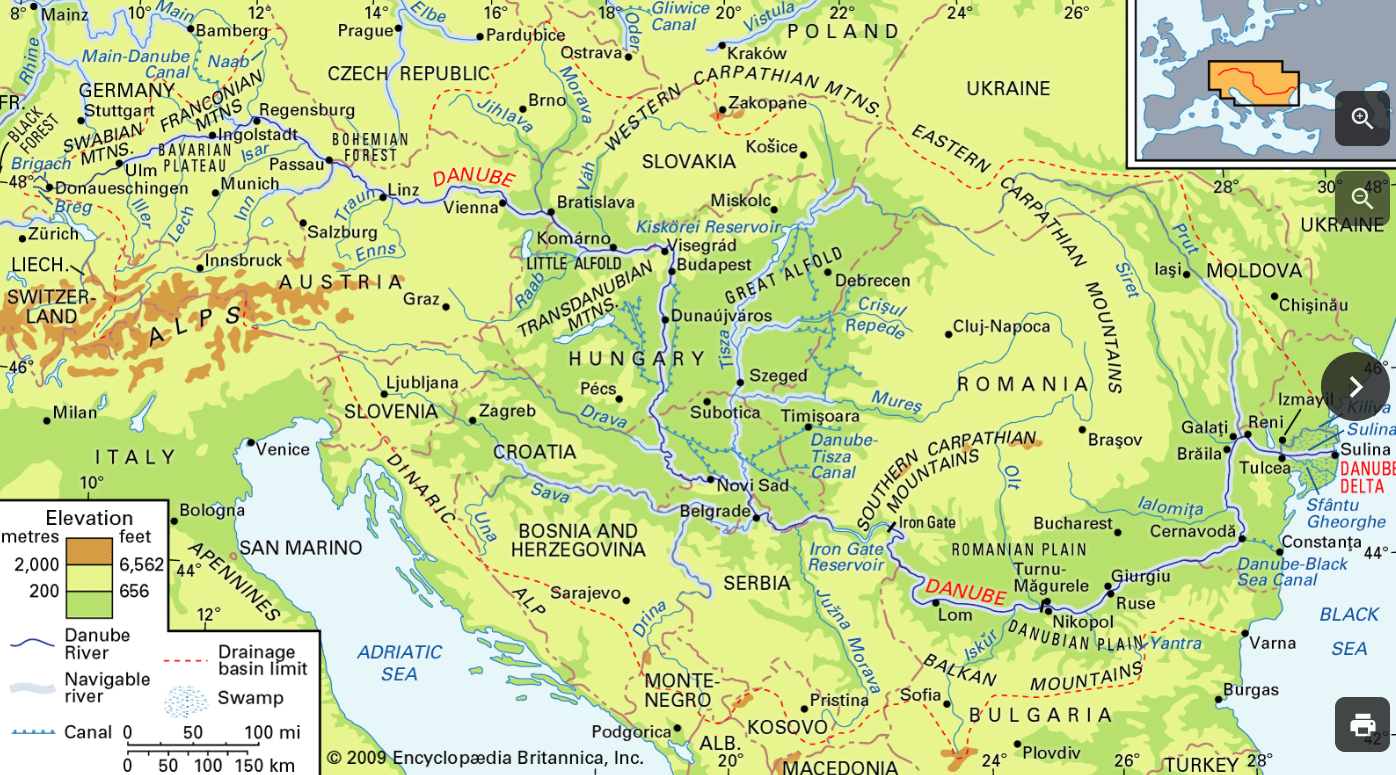

Let's look at the Danube river basin. It is huge and the real first baselevel of the Danube is the depositional Panonian Basin that starts in Vienna. Vienna has about the same elevation as the Upper Rhine Graben. Therefore, in an ideal world you would choose something like 180m elevation as baselevel for the Rhine-Danube comparison. However, then we'd need a huge DEM because we'd need the entire Danube basin until Vienna! This is impractical for your laptops and our course, so we'll need to improvise a bit.

Now we know the best baselevel. Chi is calculated only along the streams, therefore, you need to clip your stream network to the area upstream of your base level. Use the function 'griddedcontour' to make a contour and the 'modfiy' to clip your STREAMobj. Once, you've clipped your stream network you can use  'chitransform'  to calculate chi with your concavity from before.

theta_ref = 0.45;
baseLevel = 180;

Con  = griddedcontour(DEM,[baseLevel baseLevel],true);
Con.Z(:,end) = true;  
% Schi = modify(S,'upstreamto',Con);  % THIS IS HOW YOU'D NORMALLY CALULATE CHI
% chi  = chitransform(Schi,A,'mn',theta_ref);  % THIS IS HOW YOU'D NORMALLY CALCULATE CHI!!! 
% Instead we'll loada precalculated file
chi = load('chi.mat');  Schi = chi.Schi; chi = chi.chi;

Now, let's plot the chi map to look at potential disequilibrium in the drainage network and potential divide movement. We'll use the roma color map. I suggest you plot the DEM with the "gray" colorbar and then plot the chi values on top with the 'plotc' command. Try it out!

% color maps
cc = flipud(ttscm('roma'));  % load roma color map and reverse it
cg = gray;

h = figure();
set(h,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',cg(1:255,:),'colorbar',false)
% use plotc to plot the stream network colored by chi
% set colormap to cc (roma)
% show colorbar

Rivers with low chi values that are next to rivers with high chi values are likely to eat away drainage area from the high chi basins over time. Can you find such disequilibrium in the drainage network of  southwestern Germany?

Which rivers are eating away area from which other rivers?

Does this pattern connect to observations from the last lecture on river profiles?

Most of the chi maps are plotted similarly to what we've just done. But personally, I find it sometimes hard to really see the disequlibrium. Chi can only be calculated for streams, but there's a trick I use for better visibility, e.g. in this paper, figure 3 [LINK](https://doi.org/10.1016/j.gloplacha.2021.103641). You can project values from the streams onto the hillslopes by reversing the flow routing. This means that a hilllslope pixel simply gets assigned the value of the stream pixel that they eventually drain into. In TT, values that are only stored for stream nodes are referred to as nal (node attribute list). Our chi values are a "nal" but can be projected onto the hillslopes with 'mapfromnal'. Use it to make a chi map!

chiMap = % use 'mapfromnal' to make a GRIDobj of chi values. Use the correct stream network!
D = DIVIDEobj(FD,Schi); % calculate the divides. Use the correct stream network (the one you used for chi)
D =  % calculate the order of the divide to make it look prettier ;)
figure(); 
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,chiMap,'colormap',cc(1:255,:),'colorbar',true)
hold on
plot(D,'limit',[2000 inf],'color','k') % plot divides

Now, this looks much clearer and easier to interpret. You see the main divides and you should be able to pick out where the divide is supposed to move in the future.

So, it seems like the Danube basin is shrinking, as the Rhine/Neckar system is growing over time. What could be driving this change?

- Discussed in lecture and/or _key file

In the west, the Neckar is also shrinking compared to the direct Upper Rhine graben rivers. However, is that a real singal or coud there be another explanation for this chi-contrast? Same is true for the west side of the Upper Rhine Graben.

### Evidence of former shrinking?

The current landscape suggests a strong disequilibrium between Danube and Rhine. These things don't happen over night. Therefore, we can assume that his reorganization process has likely been ging on for a while. Can we see evidence for this hypothesis in the landscape?

Typical signs of river reorganization are windgaps, river elbows.

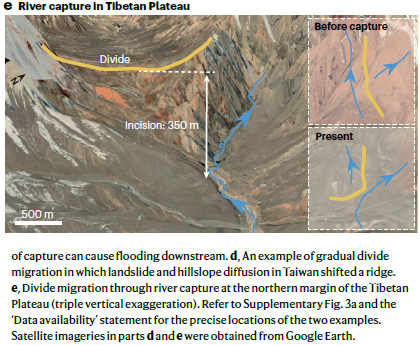

Picture of a wind gap—a drainage divide at the bottom of a valley (He et al. 2024). The river got captured and diverted towards the right in the image, leaving the old main river course "hanging" with a drainage divide forming in the former river valley.

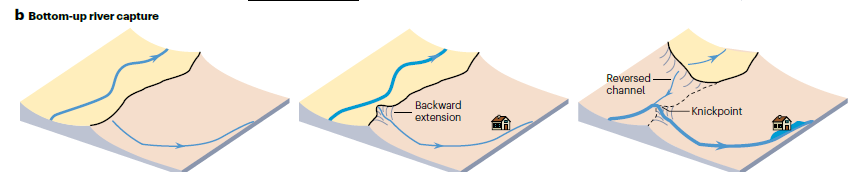

% plot the map as below, open it as a external figure window and zoom into the landscape. Can you spot such windgaps at the Rhine-Danube divide? Hint: focus on the upstream parts of the Danube drainage divide.

cc = ttscm('batlow');  % load batlow color map

Quick side note. You can find all scientific color maps included in TT with their names here: [Scientific colour maps – colour-blind friendly and accurate palettes](https://www.fabiocrameri.ch/colourmaps/)

figure(); 
set(gcf,'Units','normalized','Position',[0 0 1 1]); 
imageschs(DEM,[],'colormap',cc(1:255,:),'colorbar',true, 'caxis', [0 1300])
hold on
plot(D,'limit',[10e3 inf],'color','k') % plot divides
plotstreamorder(S,'colormap',[0, 0, 0.5],'LineWidth',max([1 2 3 4 5 6 7]/2,1))    % plot stream accroding to Strahler order

Now, take some time to search for sign of river capture. Look alog the Rhine/Neckar—Danube drainage divide. Any signs or reorganization there? Do you also see signs of reorganization in the Neckar basin or the Black Forest? Look for anomoulous river drainage patterns. 

Compare the drainage basin shape of the Danube and the Neckar. What is the obvious difference in shape?

# SINKS

Now, let's focus on sediment sinks. We've computed natural erosion rates in the previous practical. You've now also identified spatial and temporal patterns of erosion and how erosion differences drive changes in the evolution of the river network (drainage reorganization).

But where does all this eroded material go? 

Let's try and think of an algorithm to identify sedimentary sinks. There is no standard procedure to do this, so we'll have to be a bit creative. Generally, speaking sedimentary sinks will have a low slope. Otherwise it would not be possible to deposit sediment there. So, let's use a slope threshold to idenfity sinks.

slope_thres = 2;

% calculate a slope raster here

potential_sinks = % potential sinks have slope values smaller than slope_thres;

% plot area smaller than slope threshold
figure()
% use 'imageschs' if your computer is fast and and 'imagesc' if its slow
% plot potential sinks with DEM hillshade 
% imagesc(plot potential sinks) 

What value seems good at outlinig lowland floodplains without getting too many pixels on flat high elevation plateaus?

I found that using a 2 degree threshold works reasonably well at finding large river floodplains and not much else. However, this still includes lots of pixels that are high up on mountains. These are simply gentle sloping and slowly eroding surfaces without sediment deposition. How to get rid of these and only get real sinks?

## Cleaning up sinks

What is anther characteristic of active sinks? In our terrestrial environments they should be associated with a river or lake. The pixel on top of a mountain can have a low slope, but will be high above the nearest river. Thus, the height above the nearest river could be another metric to use to further refine our sinks map.

Calculate the distance above stream with 'vertdistance2stream'. Look at a histogram of the height above stream from our potential sink pixels that we got with the slope threshold. Then use the slider to find a good height threshold that nicely outlines the sinks in the river floodplains. For that, it's best to really zoom into the map and look around.

DZ = % calculate height above river using 'vertdistance2stream'

% plot a histogram of the height above river for the previously identified
% potential sinks, to get an idea for a good cut-off value
figure()
histogram(DZ.Z('potential_sinks is a logical grid. We want DZ values for all locations where potential_sinks is true.'))
xlim([-10,200])

% play around with the height threshold to identify a good threshold that
% eliminates upland pixels
height_thres = 15;

sinks = and(slope < slope_thres, DZ  < height_thres);  % make sink raster that fulfills both conditions

figure()
% plot sinks using 'imageschs' (preferred with DEM hillshade) or 'imagesc'

What slope and height above river do you suggest?

After playing around I came to the suggestion that the slope threshold of 2 degree and a 15 m height above the nearest stream work best in defining sinks. 

Interpretation time! Look at your maps of sinks. Where are they located and how does this relate to the reginal geology we've discussed previosuly in the course?

- the main sink in the area is the Upper Rhine Graben rift valley. This makes sense, active subsidence makes this an excellent sedimentary sink.

- Lake Constance is another major sediment sink. It is collecting sediment from the Alpine Rhine and will be eventually vanish as its being filled up with sediment.

- The Danube river floodplain and its tributaries from the Alps show some larger sinks. These alpine rivers carry a lot of sediment and deposit it in wide gentle river valleys.

- Other minor sediment storage occurs along most rivers to a small degree. Seidment gets stored here intermittently before being transported to the larger regional sinks.

What percentage of the study area is erosional versus depositional? Some areas could also be mostly transporting but that's harder to define.

num_sink_pixels = % use numel and find to count how many pixels are identified as sink (true value in sink raster)
total_pixels_DEM = % the total number of pixels in your DEM. The size of your DEM is stored in DEM.size
perc_sinks = % divide number of sink pixels by total pixel number

perc_erosion = 1 - perc_sinks

About 80% of the study area is erosional and only 20% act as sediment sink. The global distrobution is about 60% erosional, 20% transport, and 20% depositional ([Harrison & Lamb, 2025](https://doi.org/10.1130/G53289.1)). 

Most of our sink area are large regional sinks such as the Upper Rhine Graben. Small intermediate sinks along rivers are less prominent.

One last plot! Let's re-load our natural erosion rate map and plot the sinks on top, visualizing the entire source to sink system! The first code version I show is simple but will take some time to run and plot. Take a break or run the fast version below.

load Nat_erosion_map.mat

% % version 1 (slow but easy to code) -------------
% MS = GRIDobj2polygon(sinks, 'simplify',true);  
% figure()
% clc = viridis;
% imageschs(DEM,erosion_map, 'clim',[0,200], 'colormap',clc(1:255,:), 'colorbarlabel','erosion rate mm/ka')
% hold on
% mapshow(MS)


% version 2 (fast but a bit complicated) --------------
mask = sinks.Z;                   

figure
imageschs(DEM, erosion_map, 'colormap', clc(1:255,:)...
    , 'ticklabels','nice', 'clim',[0,200], 'colorbarlabel','erosion rate mm/ka');
axis image; hold on

overlayColor = [0.85 0.85 0.85];                       % pick your color
% overlayColor = [0.95 0.60 0.10];  % Amber if you like it more colorful

[m,n] = size(mask);
C = repmat(reshape(overlayColor,1,1,3), m, n);       % m×n×3
A = double(mask);
A(~isfinite(sinks.Z)) = 0;

xw = DEM.georef.XWorldLimits;
yw = DEM.georef.YWorldLimits;
image('XData', xw, 'YData', yw, 'CData', flipud(C), 'AlphaData', flipud(A));

% create a dummy square marker and use it in the legend
hMask = plot(gca, NaN, NaN, 's', 'MarkerFaceColor', overlayColor, 'MarkerEdgeColor', 'k','MarkerSize', 10,'DisplayName', 'Sinks');
legend(gca, 'show'); 
ScaleBar('color','w')  % add a scale bar

There you go! A map of erosion rates and where the sediment goes, with minor intermediate river fllodplain sinks and large regional sinks of Upper Rhine Graben and Lake Constance.